# Week 8 Problem 2

* Robert Garrone*

*    Worcester Polytechnic Institute, regarrone@wpi.edu*

## Introduction:

Problem 2 asks us to find the torque equations for a 2 link RR planar manipulator. An example of one is shown below for reference:

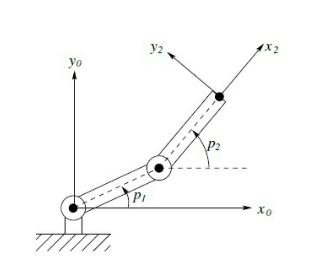 

### Approach:

The approach is to first identify the position vectors of each link and formulate expressions for the potential and kinetic energies associated with each mass related to each link. From the kinetic and potential energy equations, the Lagrangian and ultimately the force equations can be derived. 

## Materials and Methods:

The Euler-Lagrange method of solving the dynamics of a system is derived from Newton's second law which states that the motion of a particle is 

$m\ddot{y} =f-\textrm{mg}$ (6.1)

where m is its mass, $\ddot{y}$ is its acceleration upward, and $f-\textrm{mg}$ is the net force on the particle, with f being an upward force and mg being the downard force on the particle due to gravity. 

The lefthand side of this equation can be expressed as

$m\ddot{y} =\frac{d}{\textrm{dt}}\left(m\ddot{y} \right)=\frac{d}{\textrm{dt}}\frac{\partial }{\partial \dot{y} }\left(\frac{1}{2}m{\dot{y} }^2 \right)=\frac{d}{\textrm{dt}}\frac{\partial }{\partial \dot{y} }K$ (6.2)

Where $\frac{1}{2}m{\dot{y} }^2$ is the expression for kinetic energy $K$. Similarly

$\textrm{mg}=\frac{\partial }{\partial y}\left(\textrm{mgy}\right)=\frac{\partial }{\partial y}P$ (6.3)

Where $\textrm{mgh}$ is the expression for potential energy $P$. The Lagrangian $L$ is defined as the difference between the kinetic energy present in a system and the potential energy present in a system: 

$L=K-P$ (6.4)

Noting that


$$\frac{\partial }{\partial \dot{y} }L=\frac{\partial }{\partial \dot{y} }K\;\textrm{and}\;\frac{\partial }{\partial y}L=-\frac{\partial }{\partial y}P$$
 

Newton's second law can be rewritten as

$f=\frac{d}{\textrm{dt}}\frac{\partial }{\partial \dot{y} }L-\frac{\partial }{\partial y}L$ (6.5)

Equation 6.5 is the Euler-Lagrange equation and can be used to obtain force (or torque) expressions for the dynamics of a system. 

The general procedure with the Euler-Lagrange method is to determine the potential and kinetic energies of a system in terms of so-called generalized coordinates $q_{1,} \ldotp \ldotp \ldotp {,q}_n$ and then compute the equations of motion of the n-DOF system according to

$\tau_k =\frac{d}{\textrm{dt}}\frac{\partial }{\partial \dot{q_k } }L-\frac{\partial }{\partial q_k }L,k=1,\ldotp \ldotp \ldotp ,n$ (6.6)

where $\tau_k$ is the generalized force associated with $q_k$. Application of the Euler–Lagrange equations leads to a set of coupled second-order ordinary differential equations and provides a formulation of the dynamic equations of motion for serial-link robots equivalent to those derived using Newton’s second law.

## Results:    

The Euler-Lagrange method was performed on the given manipulator by hand.

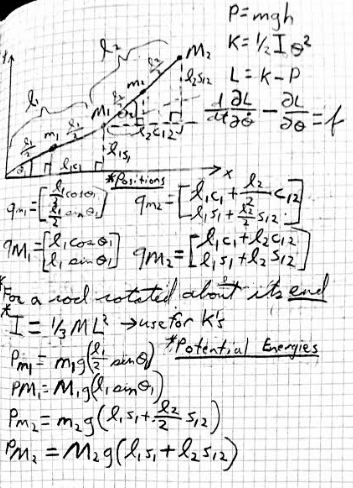

We assume that links 1 and 2 of the manipulator have masss $m_1$ and $m_2$, respectively and masses $M_1$ and $M_2$ at the ends of links. The $q$ expressions are position vectors for each mass. As this is a planar RR manipulator, the equations of energy are $K=\frac{1}{2}I\theta^2$ for kinetic energy and $P=\textrm{mgh}$ for potential energy. The equations for the potential energy at each mass is given above.

The moment of interia is given as $I=\frac{1}{3}{\textrm{ML}}^2$ for a rod (or in this case a rigid line) rotating about an end, as we have here. the length in this equation, L, is either $l\;\textrm{or}\;\frac{l}{2}$ for either link length depending on the interial moment being calculated. 

Given this, we can derive expressions for the kinetic energy of each mass, $K_{m1} {,K}_{\textrm{M1}}$ and $K_{m2} ,K_{\textrm{M2}}$We finally subtract the sum of the potential energies from the sum of the kinetic energies to obtain $L$, the Lagrangian as shown below. 

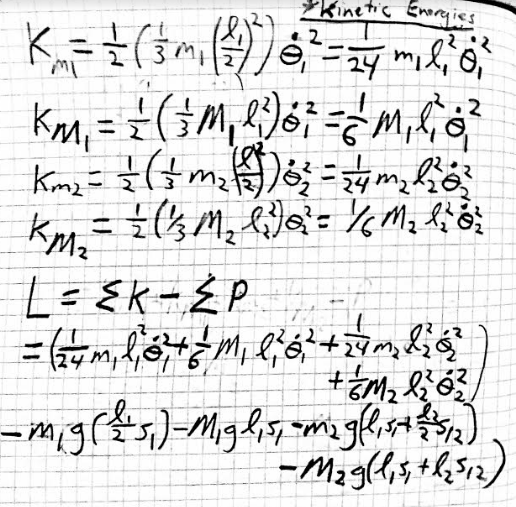

At this point, further manual computation would be excessively tedious. We can input the expressions developed by hand into MATLAB and continue calculating to obtain expressions for the torque at each joint. 

syms m_1 m_2 M_1 M_2 theta_dot_1 theta_dot_2 l_1 l_2 theta_1 theta_2 g

%potential energy of system eqns
P_m1 = m_1*g*(l_1/2)*sin(theta_1);
P_M1 = M_1*g*l_1*sin(theta_1);
P_m2 = m_2*g*(l_1*sin(theta_1)+(l_2/2)*sin(theta_1+theta_2));
P_M2 = M_2*g*(l_1*sin(theta_1)+l_2*sin(theta_1+theta_2));

%kinetic energy of system eqns
K_m1 = (1/24)*m_1*(l_1^2)*theta_dot_1^2;
K_M1 = (1/6)*M_1*(l_1^2)*theta_dot_1^2;
K_m2 = (1/24)*m_2*(l_2^2)*theta_dot_2^2;
K_M2 = (1/6)*M_2*(l_2^2)*theta_dot_2^2;

%Get Lagrangian
L = simplify(K_m1 + K_M1 + K_m2 + K_M2 - P_m1 - P_M1 - P_m2 - P_M2)

$$L = \begin{array}{l} \frac{M_{1}\,{l_{1}}^{2}\,{{\dot{\theta }}_{1}}^{2}}{6}+\frac{M_{2}\,{l_{2}}^{2}\,{{\dot{\theta }}_{2}}^{2}}{6}+\frac{{l_{1}}^{2}\,m_{1}\,{{\dot{\theta }}_{1}}^{2}}{24}+\frac{{l_{2}}^{2}\,m_{2}\,{{\dot{\theta }}_{2}}^{2}}{24}-M_{2}\,g\,\left(\sigma_{1}+l_{1}\,\sin\left(\theta_{1}\right)\right)-g\,m_{2}\,\left(\frac{\sigma_{1}}{2}+l_{1}\,\sin\left(\theta_{1}\right)\right)-M_{1}\,g\,l_{1}\,\sin\left(\theta_{1}\right)-\frac{g\,l_{1}\,m_{1}\,\sin\left(\theta_{1}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right) \end{array}$$


%take partial derivatives of Lagrangian
diff_theta_dot_1 = diff(L,theta_dot_1)

$$diff\_theta\_dot\_1 = \frac{{l_{1}}^{2}\,m_{1}\,{\dot{\theta }}_{1}}{12}+\frac{M_{1}\,{l_{1}}^{2}\,{\dot{\theta }}_{1}}{3}$$

diff_theta_dot_2 = diff(L,theta_dot_2)

$$diff\_theta\_dot\_2 = \frac{{l_{2}}^{2}\,m_{2}\,{\dot{\theta }}_{2}}{12}+\frac{M_{2}\,{l_{2}}^{2}\,{\dot{\theta }}_{2}}{3}$$

diff_theta_1 = diff(L,theta_1)

$$diff\_theta\_1 = -M_{2}\,g\,\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)\right)-g\,m_{2}\,\left(\frac{l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\cos\left(\theta_{1}\right)\right)-M_{1}\,g\,l_{1}\,\cos\left(\theta_{1}\right)-\frac{g\,l_{1}\,m_{1}\,\cos\left(\theta_{1}\right)}{2}$$

diff_theta_2 = diff(L,theta_2)

$$diff\_theta\_2 = -M_{2}\,g\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-\frac{g\,l_{2}\,m_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)}{2}$$


syms theta_ddot_1 theta_ddot_2

%sub in double dot thetas to "differentiate" w.r.t. time
%for the differential theta dot expressions above.
%Admittedly inelegant but works!
diff_t_diff_theta_dot_1 = subs(diff_theta_dot_1,theta_dot_1,theta_ddot_1)

$$diff\_t\_diff\_theta\_dot\_1 = \frac{{l_{1}}^{2}\,m_{1}\,{\ddot{\theta }}_{1}}{12}+\frac{M_{1}\,{l_{1}}^{2}\,{\ddot{\theta }}_{1}}{3}$$

diff_t_diff_theta_dot_2 = subs(diff_theta_dot_2,theta_dot_2,theta_ddot_2)

$$diff\_t\_diff\_theta\_dot\_2 = \frac{{l_{2}}^{2}\,m_{2}\,{\ddot{\theta }}_{2}}{12}+\frac{M_{2}\,{l_{2}}^{2}\,{\ddot{\theta }}_{2}}{3}$$


%torque expressions
tau_1 = simplify(diff_t_diff_theta_dot_1 - diff_theta_1)

$$tau\_1 = \frac{{l_{1}}^{2}\,m_{1}\,{\ddot{\theta }}_{1}}{12}+M_{2}\,g\,\left(l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)\right)+g\,m_{2}\,\left(\frac{l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)}{2}+l_{1}\,\cos\left(\theta_{1}\right)\right)+\frac{M_{1}\,{l_{1}}^{2}\,{\ddot{\theta }}_{1}}{3}+M_{1}\,g\,l_{1}\,\cos\left(\theta_{1}\right)+\frac{g\,l_{1}\,m_{1}\,\cos\left(\theta_{1}\right)}{2}$$

tau_2 = simplify(diff_t_diff_theta_dot_2 - diff_theta_2)

$$tau\_2 = \frac{{l_{2}}^{2}\,m_{2}\,{\ddot{\theta }}_{2}}{12}+\frac{M_{2}\,{l_{2}}^{2}\,{\ddot{\theta }}_{2}}{3}+M_{2}\,g\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+\frac{g\,l_{2}\,m_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)}{2}$$

Above, we symbolically compute the Lagrangian and its partial derivatives to be used to construct torque equations $\tau_1$ and $\tau_2$ for each revolute joint. 

## Discussion:

The equation for the torque at joint 1 and the torque at joint 2 were successfully computed partially by hand using the Euler-Lagrange method. Coding was necessary and appropriate to complete the computation for $\tau_1$ and $\tau_2$ as simplification of the expressions by hand would be time-consuming and prone to error.  

The results are intuitively satisfying. For $\tau_1$, we get an expression that is far more complex than $\tau_2$ and needs to account for both link lengths and masses $M_1$ and $m_1$ present at the first link in addition to $M_2 \;\mathrm{and}\;m_2$ of the second link. For $\tau_2$, the only link length present is the length of link 2 and the only masses present are the link 2 masses in the expression. In both torque expressions, the $\theta_1 \;\mathrm{and}\;\theta_2$ joint position variables for both links appear, meaning that the system's links are mathematically coupled for dynamics computations. 

 I made the decision to go with an expression for the moment of interia of a rod/beam rotated about its end as opposed to the moment of interia equation given in the lecture slides as I believe that equation in the slides is for a rod/beam rotated about its center of mass. Rotation about the center of mass is not what appears to be happening in the 2-link RR planar manapulator case given. This being said, I have relatively little in the way of mechanical engineering background and cannot be definitively sure in my choice of moment of intertia expression. 

While the Euler-Lagrange method presented is natural and intuitive for this relatively simple manipulator, the generalized  matrix-based form of the Euler-Lagrange method involving velocity-jacobians as described in sections 6.3 and 6.4 of Spong is the clearly superior choice when dealing with n-link robots. However, given the complexity of implementing this general method for a 2-link planar robot, I feel that the method presented above made more sense to use. 

## References:

-  Spong, M. W. (2006). *Robot Modelling and Control Mark W. Spong* (pp. 35-74) (926186803 726311037 M. W. Spong, Author). Hoboken, NJ: Wiley.

- [Moment of Inertia Equation Used](http://hyperphysics.phy-astr.gsu.edu/hbase/mi2.html#irod3)